# Explore Data

%Instructions are in the task pane to the left. Complete and submit each task one at a time.
%This code loads the table data which contains the basketball player data.
load bballData.mat
data

data = 554×22 table
      playerID                name             pos    height    weight     GP     minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers     PF     fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
    _____________    ______________________    ___    ______    ______    ____    _______    ______    _________    _________    ________    

## Task 1

You can plot some results from the basketball player data to explore relationships between various statistics and player position.

For example, the `boxplot` function can create a box plot of the points scored for each position:

`boxplot``(``data.points``,``data.pos``)`

**TASK**

Create a box plot of player height for each position.

**Hint**

Use the `boxplot` function with two inputs: `data.height` and `data.pos`.

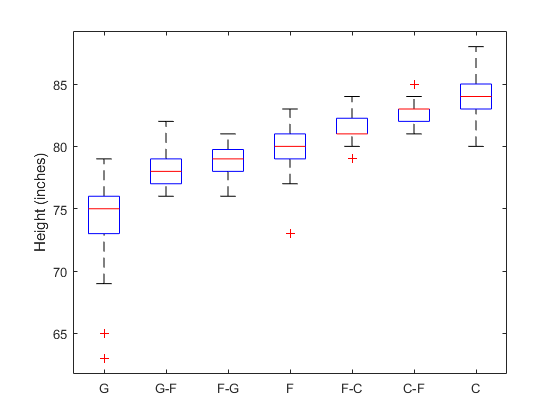

boxplot(data.height,data.pos)
ylabel("Height (inches)")

## Task 2

It looks as though guards (G) are generally shorter than forwards (F) or centers (C). What other patterns can we find in the data?

You can use `gscatter` to explore the relationship between two variables, grouped by position.

`gscatter``(``data.``varX``,``data.``varY``,``data.pos``)`

**TASK**

Plot points against rebounds, grouped by position.

**Hint**

Use the `gscatter` function with inputs `data.rebounds` then `data.points`. Use `data.pos` as the grouping variable.

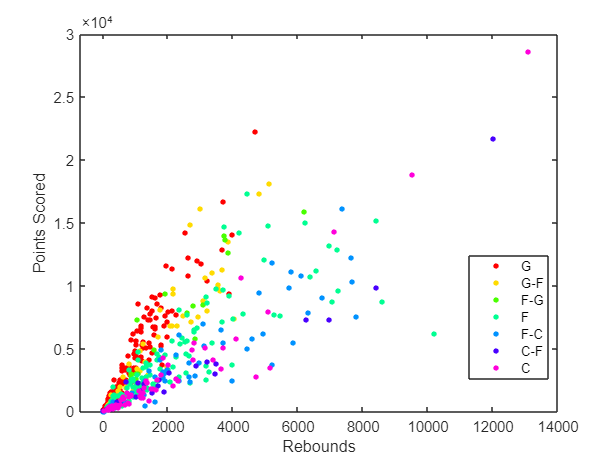

gscatter(data.rebounds,data.points,data.pos)
xlabel("Rebounds")
ylabel("Points Scored")

## Task 3

You can see some groupings for different positions. However, the data's range makes it difficult to compare players, since most players are clustered tightly around the origin.

Some players played much more than others, leading to higher total points and rebounds. One way to account for this difference is to divide points and rebounds by the number of games played.

In the table `data`, the variable `GP` contains the number of games played. You can use element-wise division (`./`) to calculate per game statistics.

`data.``variable``./``data.GP`

**TASK**

Plot points per game against rebounds per game, grouped by player position.

**Hint**

Calculate the rebounds per game and points per game using `./`.

`data.rebounds``./``data.GP`

`data.points``./``data.GP`

Then use `gscatter` with `data.pos` as the grouping variable.

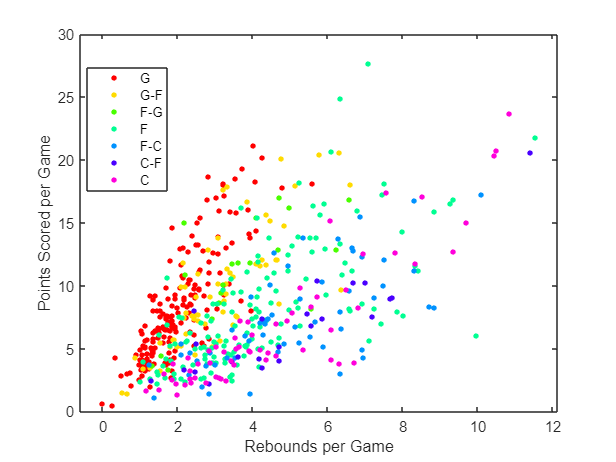

gscatter(data.rebounds./data.GP,data.points./data.GP,data.pos)
xlabel("Rebounds per Game")
ylabel("Points Scored per Game")

## Task 4

The data points are no longer clustered around the origin, but the data points for each position are still spread out. Can a different normalization yield more insight?

Another way to account for difference in play time is to divide by the number of minutes played, `data.minutes`.

**TASK**

Plot points per minute against rebounds per minute, grouped by player position.

**Hint**

Calculate the rebounds per minute and points per minute using `./`.

`data.rebounds``./``data.minutes`

`data.points``./``data.minutes`

Then use `gscatter` with `data.pos` as the grouping variable.

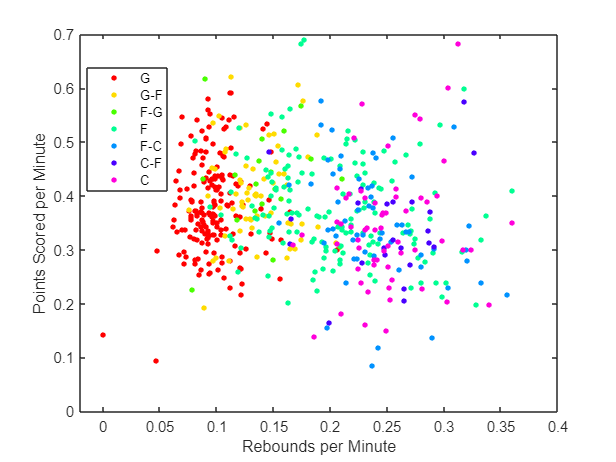

gscatter(data.rebounds./data.minutes,data.points./data.minutes,data.pos)
xlabel("Rebounds per Minute")
ylabel("Points Scored per Minute")

## Further Practice

When normalized by minutes played, you can see vertical "stripes" in the plot. This means rebounds per minute may be a useful indicator of position – centers (C) and forwards (F) tend to have more rebounds per minute than guards (G).

But each "stripe" has similar vertical range, so points per minute may **not** be a useful indicator of position – players of any position could score similar points per minute.

You can use indexing to normalize player statistics (columns 8 through 22) by minutes played.

`data``{``:,``8``:``22``}` `=` `data``{``:,``8``:``22``}``./``data.minutes`

Since total minutes played can also vary widely, you can normalize it to minutes per game.

`data.minutes` `=` `...`

    `data.minutes``./``data.GP`

Now create box plots of rebounds per minute by position and points per minute by position.

`boxplot``(``data.rebounds``,``data.pos``)`

`boxplot``(``data.points``,``data.pos``)`

data{:,8:22} = data{:,8:22}./data.minutes

data = 554×22 table
      playerID                name             pos    height    weight     GP     minutes    points     oRebounds    dRebounds    rebounds    assists      steals      blocks      turnovers       PF       fgAttempted     fgMade     ftAttempted     ftMade     threeAttempted    threeMade 
    _____________    ______________________    ___    ______    ______    ____    _______    _______    _________    _________    ________

data.minutes = ...
    data.minutes./data.GP

data = 554×22 table
      playerID                name             pos    height    weight     GP     minutes    points     oRebounds    dRebounds    rebounds    assists      steals      blocks      turnovers       PF       fgAttempted     fgMade     ftAttempted     ftMade     threeAttempted    threeMade 
    _____________    ______________________    ___    ______    ______    ____    _______    _______    _________    _________    ________

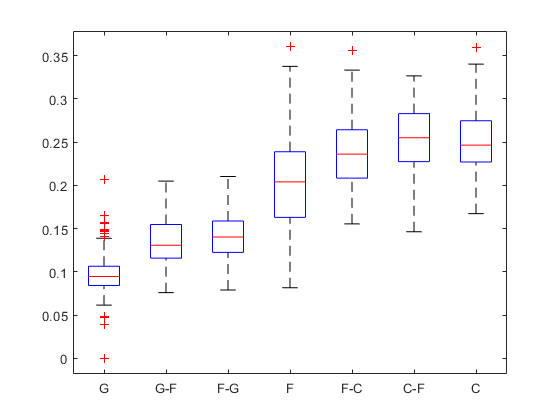

boxplot(data.rebounds,data.pos)

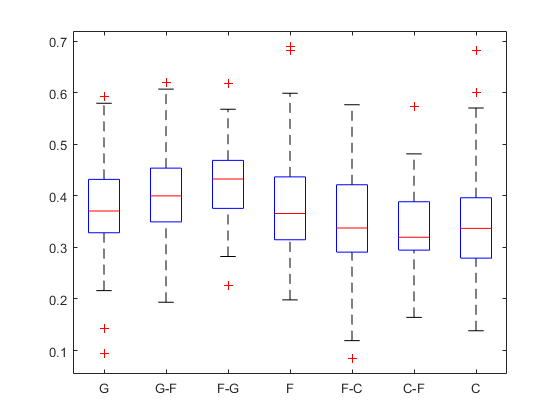

boxplot(data.points,data.pos)